**Pregunta 1**

close all
clear all
clc


% Config:
s = tf('s');

optionss=bodeoptions;
optionss.MagVisible='on';
optionss.PhaseMatching='on';
optionss.PhaseMatchingValue=-180;
optionss.PhaseMatchingFreq=1;
optionss.Grid='on';

%constantes
p=4

p = 4

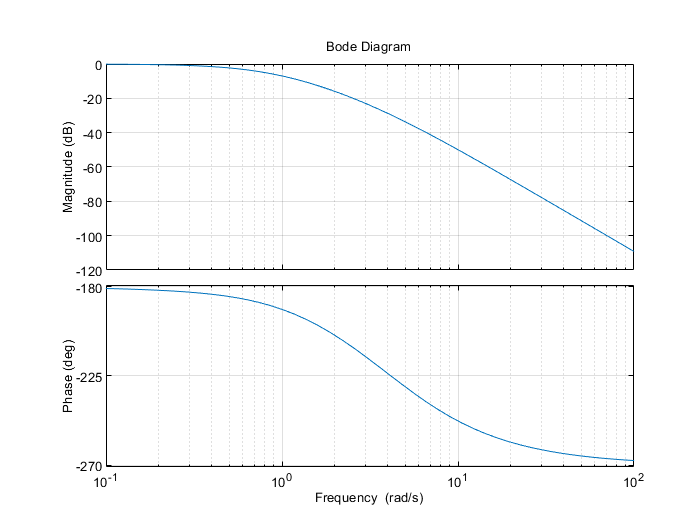


%variables de estado
orden = 3;
x=sym('x',[orden 1],'real');
u=sym('u','real');

% Punto de equlibrio 
u_e = -sin(pi/6);
x_e = [pi/6 ; 0 ; 0];

%f es mi X_punto
f1 = x(2);
f2 = sin(x(1)-0.1*x(2)+x(3));
f3 = p*(u-x(3));

f = [f1;f2;f3];

%g es mi salida 
g = x(1);

A = jacobian(f,x);
A = double(subs(A,{x(1),x(2),x(3),u},{x_e(1),x_e(2),x_e(3),u_e}));

B = jacobian(f,u);
B = double(subs(B,{x(1),x(2),x(3),u},{x_e(1),x_e(2),x_e(3),u_e}));

C = jacobian(g,x);
C = double(subs(C,{x(1),x(2),x(3),u},{x_e(1),x_e(2),x_e(3),u_e}));

D = jacobian(g,u);
D = double(subs(D,{x(1),x(2),x(3),u},{x_e(1),x_e(2),x_e(3),u_e}));

% Transferencia de la Planta Linealizada
Planta = tf(ss(A,B,C,D));


figure(); 
bode(Planta,optionss);

Se observa en el pzmap que la planta linealizada presenta un polo en el SPD, por lo que es inestable.

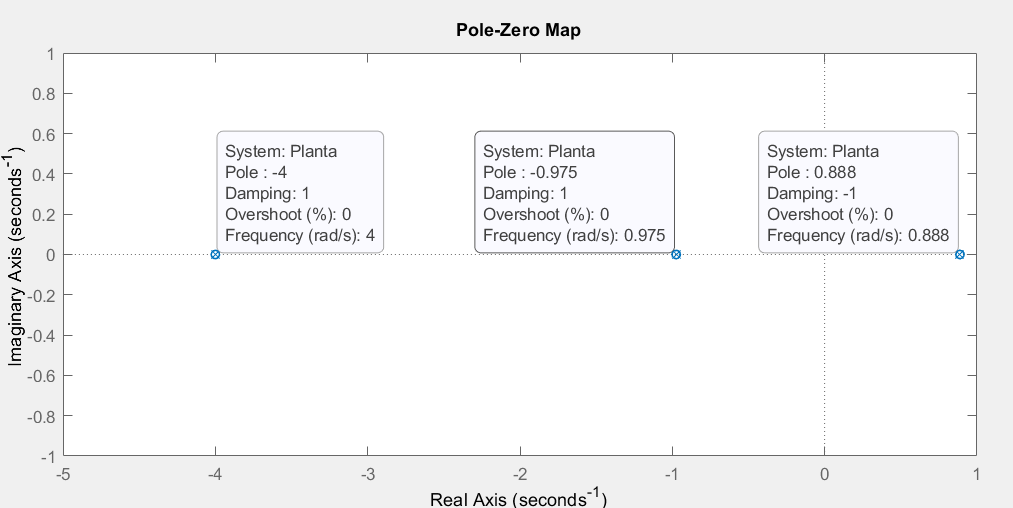

**Item D en adelante)**

**Para el problema anterior, encontrar un compensador con acción integral que cumpla: **

**  d. MF 60 grados.**

**  e. Proponer un 𝑇𝑠 de muestreo para implementar el control digital.**

**  f.  Simular en Simulink con control en tiempo discreto. Respuesta escalón de 2 grados (2 ⋅ 180 /pi rad)**

**g. Graficar respuestas en frecuencia de S(s), T(s), PS(s) y CS(s).  **

**h. Calcular el margen de estabilidad “𝑠𝑚”. **

** i.  Máxima acción de control igual a 1000 en valor absoluto para la implementación digital. **

Primero divido a la planta en pmp y pap

pap = (s+0.888)/(s-0.888);
pmp = 3.464*(1/((s+4)*(s+0.975)*(s+0.888)));

Luego, agrego el controlador integral y dos polos alejados para garantizar que el numerador del controlador no sea mayor al del denominador y observo el root locus:

% rlocus(1*Planta/(pmp*s*(s+100)*(s+100)))

 Busco el amortiguamiento crítico de estas dos ramas del root locus para elegir el K a utilizar.

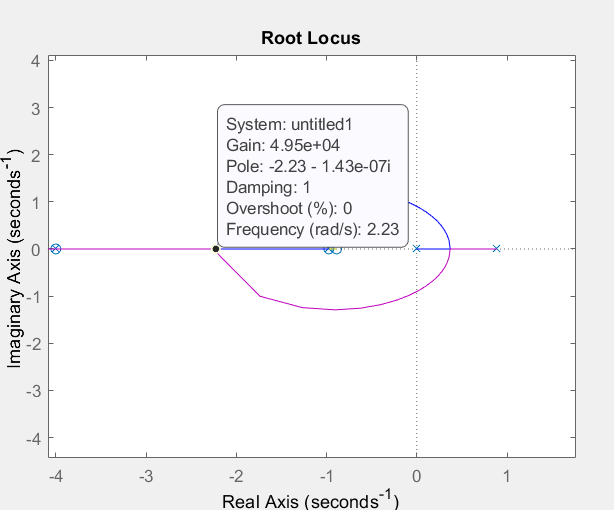

Defino entonces un k = 50000. El controlador sería el siguiente:

k=50000;
controlador = k/(pmp*s*(s+100)*(s+100))

controlador =
 
  50000 s^3 + 293150 s^2 + 415890 s + 173160
  ------------------------------------------
       3.464 s^3 + 692.8 s^2 + 34640 s
 
Continuous-time transfer function.



El margen de fase resultante es el siguiente:

% bode(controlador*Planta, optionss)

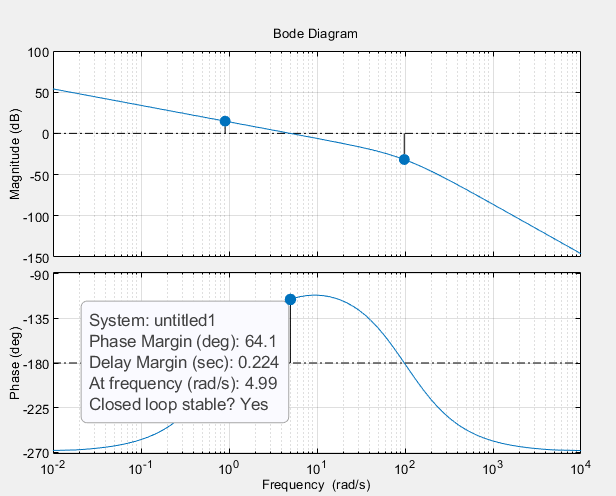

Se observa que el MF = 64.1°, por lo que lo dejo asi, para luego al aplicar un Ts tal que me reste 5° MF, el sistema total me quede en 60°MF.

Resta calcular Ts tal que me reste como mucho 5° MF.

% T = [0.1 0.22 0.01 0.0075 0.05 0.04 0.03 0.02 0.001];
% 
% 
% figure()
% bode(controlador*Planta, optionss, 'black');
% grid on
% hold on
% for i=1:length(T)
%     T(i)
%     Pad=(1-T(i)/4*s)/(1+T(i)/4*s);
%     bode(controlador*Planta*Pad, optionss)
% end
% 
% legend('L', '0.1', '0.22',' 0.01 ', '0.0075','0.05 ','0.04 ','0.03 ','0.02 ','0.001')
% hold off

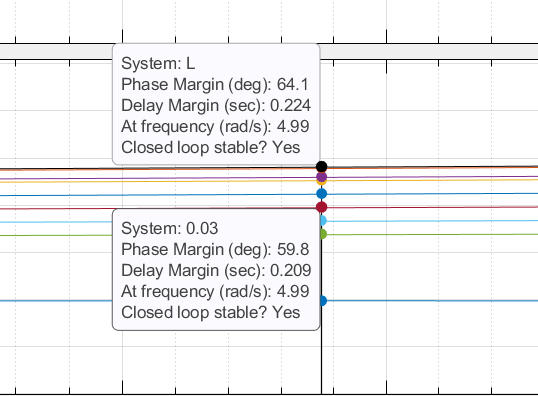

Se observa en la imagen que para un Ts = 0.03, se obtiene un MF = 59.8°, lo que cumple con lo pedido.

Finalmente, resulta:

pade_final = (1-0.03/4*s)/(1+0.03/4*s);
L = controlador*Planta*pade_final;
c_digital = c2d(controlador,0.03,'tustin');
% bode(L, optionss)

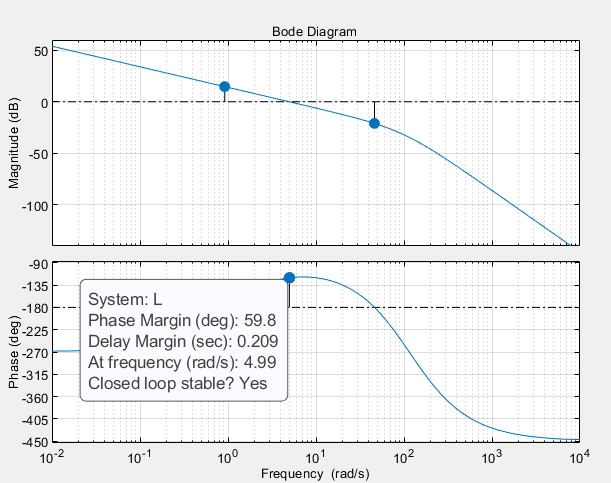

Grafico el grupo de las 4: 

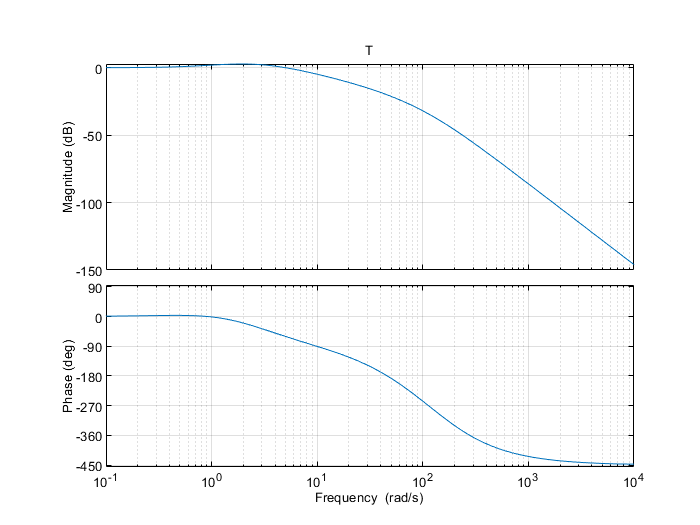

T_transf = minreal(L/(1+L)); 
figure() 
bode(T_transf,optionss);title('T');

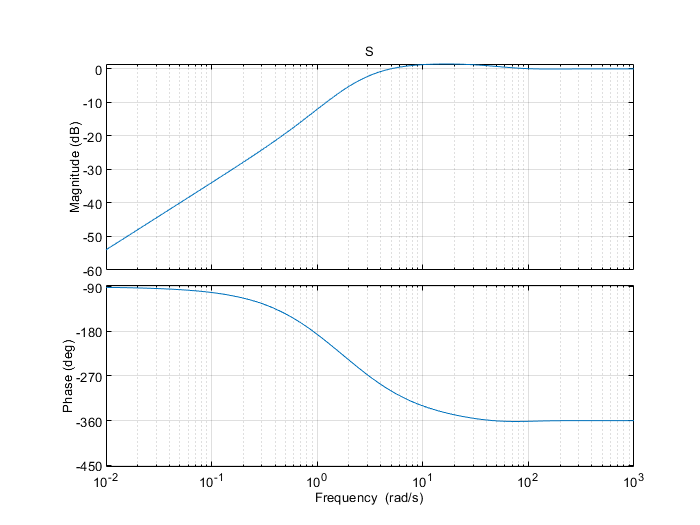

S_transf = 1 - T_transf;  
figure()
bode(S_transf,optionss);title('S');

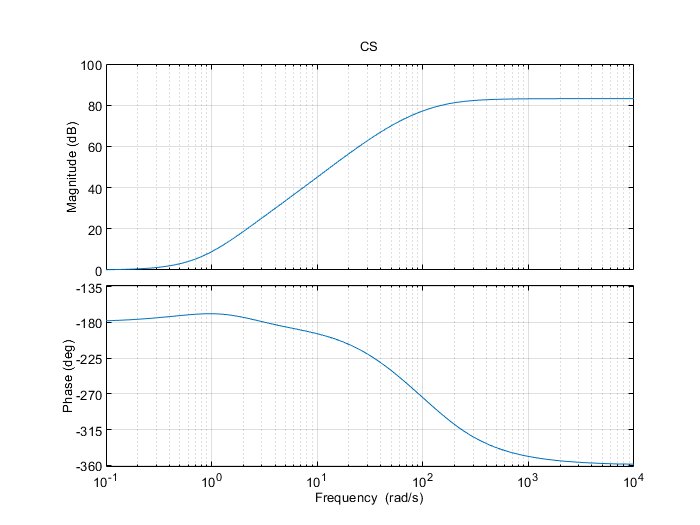

CS = minreal(controlador*S_transf); 
figure()
bode(CS,optionss);title('CS');

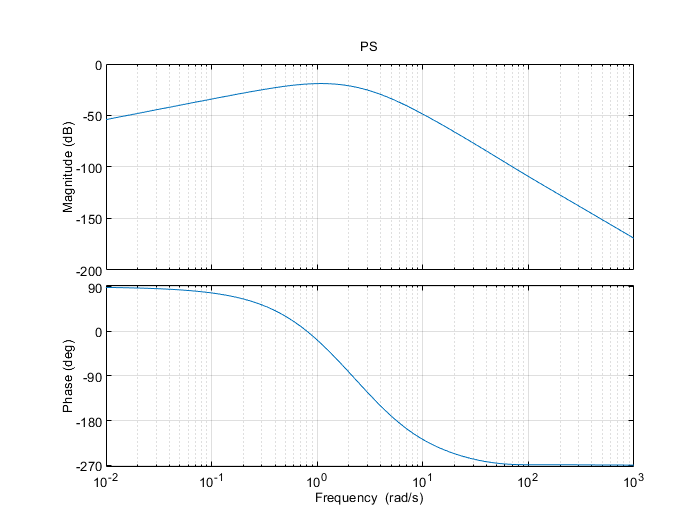

PS = minreal(Planta*S_transf);
figure()
bode(PS,optionss);title('PS');

Para calcular el márgen de estabilidad, basta con graficar el diagrama de bode de S y observar su valor máximo en el diagrama de magnitud. 

% S_transf = 1 - T_transf;  
% figure()
% bode(S_transf,optionss);title('S');

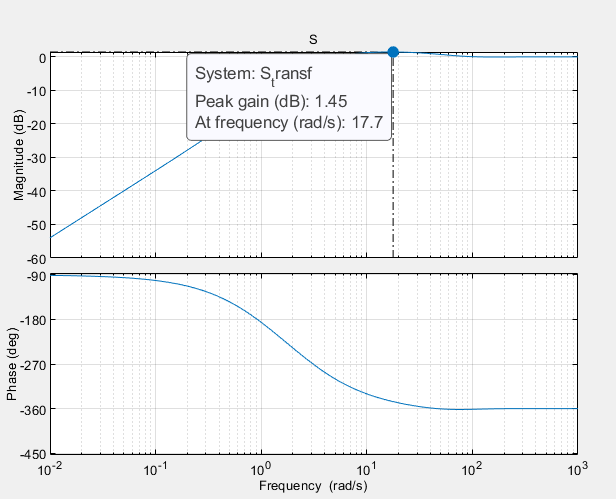

Se nota que el valor máximo es de 0.919dB. El margen de estabilidad se calcula como 1/sobrepico.

s_m = 1/db2mag(1.45)

s_m = 0.8463

Esto da como resultado un margen de estabilidad s_m = 0.8463